# **Simulation eines Volgelschwarms**

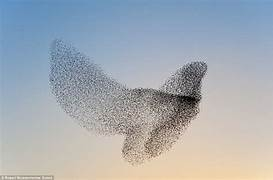

### **Grundidee**

1986 fertigte Craig Reynolds ein Computermodell koordinierter Tierbewegungen wie Vogel- und Fischschwärme an [1]. Es basierte auf einer dreidimensionalen Rechengeometrie, wie sie normalerweise im computergestützten Design verwendet wird. Die generischen simulierten Flockkreaturen werden Boids genannt. Das grundlegende Modell besteht aus drei einfachen Steuerverhaltensweisen, die beschreiben, wie ein einzelnes Boid-Manöver basierend auf den Positionen und Geschwindigkeiten seiner nahen Flockgenossen abläuft.

### **Fortbewegung**

Jeder Boid hat direkten Zugriff auf die geometrische Beschreibung der gesamten Szene, aber die Beflockung erfordert, dass er nur auf Herdenmitglieder innerhalb eines bestimmten Abstands um sich herum reagiert. 

### 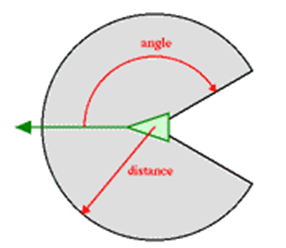

Die Nachbarschaft ist gekennzeichnet durch eine Entfernung und einen Winkel. Herdenmitglieder außerhalb dieser lokalen Nachbarschaft werden ignoriert. Sie ist als die Region zu verstehen, in der die Herdenmitglieder Einfluss auf die Steuerung haben. Wenn zwei Vögel zu nah sind, überschreibt die Regel "Separation" die beiden anderen, die deaktiviert werden, bis die minimale Trennung erreicht ist. Die drei Regeln betreffen nur den Kurs des Vogels. Jeder Vogel bewegt sich immer mit gleicher konstanter Geschwindigkeit vorwärts.

Quelle:

[1] Reynolds, C. W. (1987) Flocks, Herds, and Schools: A Distributed Behavioral Model, in Computer Graphics, 21(4) (SIGGRAPH '87 Conference Proceedings) pages 25-34.

[2] Wilensky, U. (1998). NetLogo Flocking model. http://ccl.northwestern.edu/netlogo/models/Flocking. Center for Connected Learning and Computer-Based Modeling, Northwestern University, Evanston, IL.

## 1) Erklären Sie kurz die folgenden Begriffe unter Verwendung der Vorlesung und der angeführten Quellen.

- Separation: Die Vögel bewegen sich auseinander wenn sie zu nah an anderen Vögeln fliegen.

- Ausrichtung: Sie versuchen, ihre Richtung der von anderen anzupassen.

- Zusammenhalt: Außerdem versucht jeder Vogel, nicht zu weit vom Zentrum seines Schwarms entfernt zu sein, um so Zusammenhalt des Schwarms zu gewährleisten.

## 2) Vorbereitung

Um eine gute Basis für die Implementierung zu schaffen erarbeiten Sie sich die nachstehenden Fragen.

('Geschwindigkeit' ist irreführend, da alle gleich schnell fliegen. Richtung trifft es eher?)

- Wie viele Information muss der Agent haben um diese Regeln abzubilden?

Eigene Position und Geschwindigkeit sowie die Positionen und Geschwindigkeiten der Agenten in seiner Sicht/Umgebung.

- Welche Information muss daher jeden Zeitschritt ermittelt werden?

Alle Positionen und Geschwindigkeiten.

- Welche Parameter möchte ich beim Funktionsaufruf modifizieren können?

Die konstanten, die das Gewicht jeder Regel bestimmen (alphas in den Folien) und vielleicht den Sichtradius r bzw. Sichtwinkel gamma der Vögel.

- Definieren Sie für ihre Implementierung die Nachbarschaft eines Boids.

N((x,v1)) = {(y,v2) in der Menge aller boids : |`x-y| < r, acos((y-x)/(` |`x|` |`y|)) < gamma} \ (x,v1)`

`(gamma ist sichtwinkel links und rechts)`

## 3) Implementierung

Erstellen Sie ein Lauffähiges Programm und definieren Sie mindestens für die Regel "Zusammenhalt" eine externe Funktion. Auch für den Plotbefehl kann eine exterene Funtion nicht Schaden.

### Parameter Initialisierung

% parameter [alpha0,alpha1,alpha2,alpha3] Folie 25 Case Studies
%para1=[1,2,3,4];

% weights: 1 for last vel, 2 for zusammenhalt, 3 for ausrichtung, 4
% separation
para1=[1,0.3,1,1.5];

% n ... number of birds
n = 100

n = 100


% visualization parameters
c = 10

c = 10

lim_vis = [-c c -c c]

lim_vis =    -10    10   -10    10



A = rand(n,4) *100 - 50; % 4 informations each: x_pos, y_pos, x_vel, y_vel
r = 30; % neighborhood radius
r_c = 0.5; % collision_radius
gamma = 130; % degrees



% all velocities are the same, so I need to normalize here and in each step
A(:,[3,4]) = normr(A(:,[3,4]))

A =   -24.7876  -25.4279   -0.9903    0.1391
  -25.3007   -1.9878    0.4975   -0.8675
  -26.0424   16.8972    0.8786    0.4775
   -7.1749   35.2376   -0.5577   -0.8300
   32.5926   44.5323   -0.9756    0.2197
   11.7186  -37.1268   -0.9699   -0.2435
  -30.6126   19.6645   -0.6753   -0.7376
   30.8081  -41.9916   -0.8097   -0.5868
   48.5634  -39.6437    0.7827    0.6224
  -35.1398  -36.8802   -0.5371    0.8435


alpha =     1.0000    0.3000    1.0000    1.5000


counter = 0

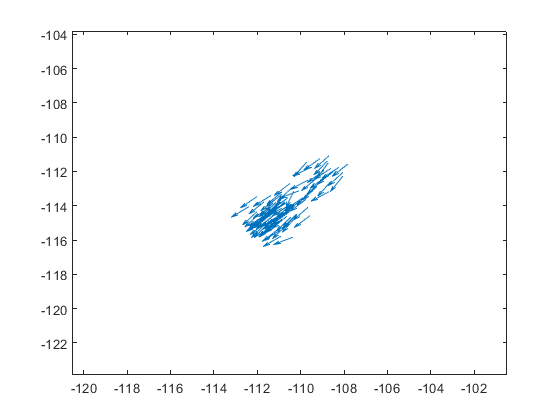


bird_flock(A,para1,r,gamma,"neighborhood",r_c,lim_vis)

### Algorithmus für Vogelschwarm-Simulation

Sie können hier auch nested MATLAB-Functions verwenden indem Sie diese nach der Hauptfunktion definieren. Es können hier natürlich auch alle 3 Regeln ausgelagert werden.

% Bird Flocking Implementation


function [animation] = bird_flock(A, alpha, r, gamma, swarm_mode, collision_radius, lim_vis)
    n = size(A,1);
    
    alpha
    
    A_current = A;
    A_new = zeros(size(A));
    max_iterations = 1000;
    counter = 0
    fig = figure;
    axis([xlim,ylim])
    
    while counter < max_iterations
        counter = counter + 1;
    
        d1 = zeros(n,2);
        d2 = zeros(n,2);
        d3 = zeros(n,2);
        
        for idx = 1:n
            % ZUSAMMMENHALT
            % i don't nee two implementations, instead I will just write one
            % function and use either the neighborhood or all other data as
            % input
            neighbors = neighborhood(idx,A_current,r,gamma);
            collision_neighbors = neighborhood(idx,A_current,collision_radius,gamma);
            
            if swarm_mode == "neighborhood"
                zusammenhalt(A_current, neighbors, idx);
                
                d1(idx,:) = zusammenhalt(A_current, neighbors, idx);
            elseif swarm_mode == "all"
                all_but_idx = [1:idx-1,idx+1:n];
                d1(idx,:) = zusammenhalt(A_current,all_but_idx,idx);
            else
                "WARNING: No swarm mode specified. Default is 'neighborhood' "
                d1(idx,:) = zusammenhalt(A_current, neighbors, idx);
            end
            
            % AUSRICHTUNG
            d2(idx,:) = ausrichtung(A_current, neighbors, idx);
            
            % SEPARATION
            d3(idx,:) = separation(A_current,collision_neighbors,idx);
            
        end
            
        %UPDATE (outside of loop because I packed all calculated values in
        %matrices anyways)
        % locations
        A_new(:,[1,2]) = A_current(:,[1,2]) + A_current(:,[3,4]);
        % velocities (normr again to enforce that everything moves in same
        % velocity)
        
        weighted_addition = A_current(:,[3,4])*alpha(1) + d1*alpha(2) + d2*alpha(3) + d3*alpha(4);
        A_new(:,[3,4]) = normr(weighted_addition);
        % includes all precalculated values of d_i
        
        % moving frame, is this a good idea?
        real_centroid = sum(A_current(:,[1,2]),1)/size(A_current,1);
        new_lim_vis([1,2]) = lim_vis([1,2]) + real_centroid(1);
        new_lim_vis([3,4]) = lim_vis([3,4]) + real_centroid(2);
        visualize(A_current,new_lim_vis)
        
        pause(0.1)
        % overwrite former current matrix
        A_current = A_new;
            
            
            
            

            
            
    end
    
    


end



%%  Nachbarschaft
function [neighborhood_indices] = neighborhood(idx, A, r, gamma)
n = size(A,1);
% check for viewing angle
other_indices = [1:idx-1, idx+1 : n];

% directions to others, normalized (normr normalizes each row)
direction_to_others = normr(A(other_indices,[1,2]) - A(idx,[1,2]));

angles = acos(sum(direction_to_others .* A(idx,[3,4]),2));

% convert gamma to rad
rad_gamma = deg2rad(gamma);

% these are all indices of boids in sight (logical)
seen = zeros(n,1);
% important to include the original as 0 in the logical vector
seen(other_indices) = angles < rad_gamma;

distances = vecnorm(A(other_indices,[1,2])-A(idx,[1,2]),2,2);


close = zeros(n,1);
close(other_indices) = distances < r;


% logical and checks that only indices with boids BOTH close and in sight
% get chosen

neighborhood_indices = find(and(close,seen)); % find converts to actual indices

    
end



### Implementierung der "Zusammenhalt"-Regel

Implementieren Sie hier die Regel, dass ein einzelner Vogel immer in Richtung des Schwerpunktes seiner unmittelbaren Nachbarn tendiert

% Zusammenhalt Regel mit Zentrum der Nachbarschaft

function [d1k] = zusammenhalt(A, swarm_indices, idx)
pos = A(idx,[1,2]);
    
swarm = A(swarm_indices,[1,2]);
    

centroid = sum(swarm,1)/size(swarm,1);

% TODO ist es nicht seltsam, hier laut folien die skalierung beizubehalten?
% fragen?
% Man könnte auch die d_i normieren?
d1k = centroid-pos;
    
    
end


### Implementierung einer zweiten "Zusammenhalt"-Regel

Implementieren Sie hier die Regel so, dass ein einzelner Vogel immer in Richtung des Schwerpunktes des ganzen Schwarms tendiert. Führen Sie einen Parameter in der Hauptfunktion ein, so dass zwischen den beiden Implementierungen einfach gewechselt werden kann.

% Zusammenhalt Regel mit Zentrum des Schwarms

%Unterscheidung passiert in Hauptfunktion



### Implementierung der Ausrichtung

% Ausrichtung regel
function [d2k] = ausrichtung (A, swarm_indices, idx);
velocities = A(swarm_indices, [3,4]);
d2k = sum(velocities,1)/size(velocities,1);
end

### Implementierung der Separation

% Separation regel
function [d3k] = separation(A, collision_swarm_indices, idx)
swarm = A(collision_swarm_indices,[1,2]);
if size(swarm,1) ==0
    d3k = [0,0];
else
    push = A(idx,[1,2]) - swarm;
    
    centroid = sum(push,1)/size(push,1);
    
    d3k = centroid;
end

end

### Implementierung der Visualisierung

% Visualisierung des Schwarms

function [animation] = visualize(A,lim_vis)


positions = A(:,[1,2]);
velocities = A(:,[3,4]);

% debugging:
% for i = length(velocities)
%     if norm(velocities(i,:)) ~= 1
%         velocities(i,:)
%         norm(velocities(i,:))
%         'not good'
%     end
% end
scale = 0;
quiver(positions(:,1),positions(:,2),velocities(:,1),velocities(:,2),scale,"AutoScale","off")
axis(lim_vis);
end



